# Uso de la función wsa_dirspectrum

Esta funcion estima el espectro de energía direccional a partir de mediciones en tres direcciones ortogonales capaces de proporcionar informacion direccional.

La distribucion direccional se estima empleando el metodo de máxima entropia de Lygre & Krogstad (1986). Los coeficientes de la serie de Fourier implicados en el cálculo se estiman dependiendo del tipo de mediciones realizadas. Las densidades espectrales y cruzadas se estiman empleando el método de Welch-Barlett.

Métodos disponibles:

- PUV : presion y velocidades horizontales.

- SUV : elevacion superficial y velocidades horizontales.

- HPR : heave, pitch y roll.

## Inicializacion

clc; clear; close all;

## Datos de entrada

Para mostrar el uso de la función, en la carpeta *\toolbox\example_data* se colocó un struct con datos reales de una campaña de medición de AWAC.

data = load('burst_data.mat');

Se extrae la informacion necesaria para estimar espectros direccionales basados en metodos SUV y PUV.

- AST: señal de superficie libre (preprocesada mediante despike y filtrado) [m].

- Pressure: señal de presión (preprocesada mediante filtrado) [dBar].

- U: velocidad orbital horizontal Este [m/s].

- V: velocidad orbital horizontal Norte [m/s].

- fs: frecuencia de muestreo [Hz].

- ast_mean: distancia media a la superficie desde el sensor AWAC, se utiliza para estimar la profundidad [m].

- cell_position: posicion de la celda de medicion de velocidades respecto al sensor AWAC [m].

- mounting_height: altura de montaje del sensor AWAC [m].

- h: profundidad del lecho marino [m].

- z_p: distancia de la superficie libre al sensor (negativo hacia abajo) [m].

- Kp_min: umbral de Kp mínimo empleado.

- z_v: distancia de la superficie libre a la celda de medición de velocidades (negativo hacia abajo) [m].

AST = data.burst_data.processed.ast(:, 1);
Pressure = data.burst_data.processed.pressure;
U = data.burst_data.processed.velocity_enu(:, 1);
V = data.burst_data.processed.velocity_enu(:, 2);

fs = data.burst_data.general.fs;
ast_mean = data.burst_data.general.ast_mean;
cell_position = data.burst_data.general.cell_position;
mounting_height = data.burst_data.general.mounting_height;

h   = ast_mean + mounting_height;
z_p = -ast_mean;
z_v = cell_position - ast_mean;

## Espectro direccional basado en SUV

### Parámetros por defecto 

El método SUV requiere que se indiquen los parametros *z_v* y *h*; caso contrario se presenta un error. Por defecto el espectro direccional se calcula con 64 grados de libertad y 180 divisiones angulares.

[out_DirSpec, info_DirSpec] = wsa_dirspectrum(AST, U, V, fs, 'SUV', ...
                                             'z_v', z_v, ...
                                             'h', h);

El struct *out_DirSpec* contiene 2 substructs: Fourier y MEM. Cada uno de estos corresponde a resultados de los métodos de Serie de Fourier Truncada (TFS) y Método de Máxima Entropía de Lygre & Krogstad (MEM-I). Para el presente ejemplo se muestran los resultados MEM.

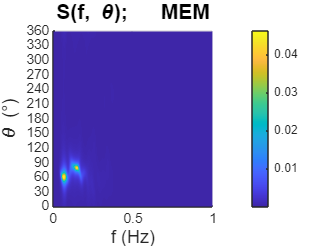

f = out_DirSpec.MEM.f;
theta = out_DirSpec.MEM.theta;
E = out_DirSpec.MEM.E;

xdir_out = 'reverse';   %Orientacion del eje de direcciones. 
DirMethod = 'MEM';      %Para el título unicamente.
plot_DirSpec(f, theta, E, xdir_out, DirMethod)

El struct *info_DirSpec* contiene información del cálculo: el momento de orden cero y substructs.

info_DirSpec

info_DirSpec = struct with fields:
           method: "suv"
           Ntheta: 180
    DoF_requested: 64
    info_spectrum: [1×1 struct]
      info_coeffs: [1×1 struct]
          Fourier: [1×1 struct]
              MEM: [1×1 struct]


El substruct *info_spectrum* contiene la información de cálculo del espectro frecuencial asociado al espectro direccional estimado.

info_DirSpec.info_spectrum

ans = struct with fields:
                 M: 2013
                 N: 122
                N0: 61
                 K: 32
              Nfft: 1024
               DoF: 64
            window: "hann"
                fs: 2
          varianza: 0.1114
                m0: 0.1144
    error_relativo: 2.6755
     resolution_Hz: 0.0164
      resolution_s: 61
         InputType: "surface"


El substruct *info_coeffs* contiene la información de cálculo asociada a cada densidad espectral cruzada empleada en el cálculo de los coeficientes de la serie de Fourier.

info_DirSpec.info_coeffs

ans = struct with fields:
    info_S11: [1×1 struct]
    info_S22: [1×1 struct]
    info_S33: [1×1 struct]
    info_S12: [1×1 struct]
    info_S13: [1×1 struct]
    info_S23: [1×1 struct]


El substruct *info_DirSpec.MEM* muestra información del método MEM. Por ejemplo, *D_is_pos* indica si la función de distribución direccional D es positiva, así como *min_D_value* indica su valor mínimo.

info_DirSpec.MEM

ans = struct with fields:
             D_nonnegative_flag: [511×1 logical]
                    D_min_value: [511×1 double]
                  D_finite_flag: [511×1 logical]
    D_area_before_normalization: [511×1 double]
             max_imaginary_part: [511×1 double]
              all_D_nonnegative: 1
                   global_min_D: 0.0051
                    constraints: [1×1 struct]
               double_peak_flag: [511×1 logical]
              double_peak_error: [511×1 double]
           constraint_tolerance: 1.0000e-10
          nonnegative_tolerance: 1.0000e-04
                       D_is_pos: 1
                    min_D_value: 0.0051
                             m0: 0.1141


### Indicando los grados de libertad

Al aumentar los grados de libertad, disminuye la varianza del espectro.

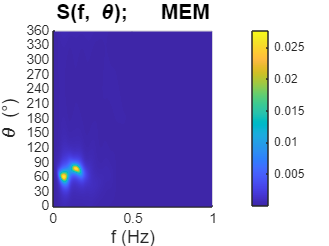


out_DirSpec = wsa_dirspectrum(AST, U, V, fs, 'SUV', ...
                                             'z_v', z_v, ...
                                             'h', h, ...
                                             'DoF', 128);
f = out_DirSpec.MEM.f;
theta = out_DirSpec.MEM.theta;
E = out_DirSpec.MEM.E;

xdir_out = 'reverse';   %Orientacion del eje de direcciones. 
DirMethod = 'MEM'; %Para el título unicamente.
plot_DirSpec(f, theta, E, xdir_out, DirMethod)

## Espectro direccional basado en PUV

### Parámetros por defecto 

El método PUV requiere que se indiquen los parametros un, z_p, z_v y h. Por defecto el valor de Kp mínimo corresponde a 0.2.

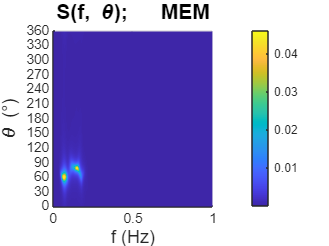

out_DirSpec = wsa_dirspectrum(Pressure, U, V, fs, 'PUV', ...
                                             'un', 'dBa', ...
                                             'z_p', z_p, ...
                                             'z_v', z_v, ...
                                             'h', h);
f = out_DirSpec.MEM.f;
theta = out_DirSpec.MEM.theta;
E = out_DirSpec.MEM.E;

xdir_out = 'reverse';   %Orientacion del eje de direcciones. 
DirMethod = 'MEM';      %Para el título unicamente.
plot_DirSpec(f, theta, E, xdir_out, DirMethod)

### Indicando el umbral de Kp

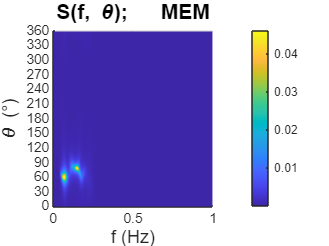


out_DirSpec = wsa_dirspectrum(Pressure, U, V, fs, 'PUV', ...
                                             'un', 'dBa', ...
                                             'z_p', z_p, ...
                                             'z_v', z_v, ...
                                             'h', h, ...
                                             'Kp_min', 0.04);
f = out_DirSpec.MEM.f;
theta = out_DirSpec.MEM.theta;
E = out_DirSpec.MEM.E;

xdir_out = 'reverse';   %Orientacion del eje de direcciones. 
DirMethod = 'MEM';      %Para el título unicamente.
plot_DirSpec(f, theta, E, xdir_out, DirMethod)

## Espectro direccional TFS

A modo de ejemplo, a continuación se muestra el resultado del método de Serie de Fourier Truncada.

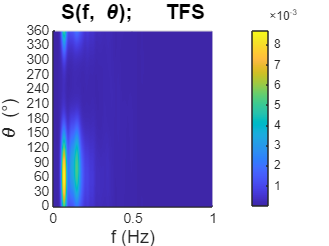

[out_DirSpec, info_DirSpec] = wsa_dirspectrum(AST, U, V, fs, 'SUV', ...
                                             'z_v', z_v, ...
                                             'h', h);

f = out_DirSpec.Fourier.f;
theta = out_DirSpec.Fourier.theta;
E = out_DirSpec.Fourier.E;

xdir_out = 'reverse';   %Orientacion del eje de direcciones. 
DirMethod = 'TFS'; %Para el título unicamente.
plot_DirSpec(f, theta, E, xdir_out, DirMethod)